# Undetermined Coefficients

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

The method of undetermined coefficients is a powerful technique for solving a common class of linear, second-order, nonhomogeneous ordinary differential equations. This method applies when the nonhomogeneous term has a specific form that directly suggests the form of a particular solution. In this script, we'll explore this method through theory, examples, and applications in pendulum motion and chemical bonds.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternatively, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Method of Undetermined Coefficients

### Why Use This Method?

The method of undetermined coefficients is used to find particular solutions to linear, second-order, nonhomogeneous ordinary differential equations of the form:


$$ay'' + by' + cy = g(x)$$
 
$$(\star)$$


where $y = y(x)$ is the solution, $a$, $b$, and $c$ are constants, and $g(x)$ is a nonzero term, or **forcing function**, with a specific form. The **particular solution**, $y_p$, is a solution to equation $(\star)$ with $a\frac{d^2y_p}{dx^2} + b\frac{dy_p}{dx} + cy_p = g(x)$, and a **general homogeneous solution**, $y_h$, is the sum of two linearly independent homogeneous solutions to $ay'' + by' + cy = 0$, as discussed in [Characteristic Equations](matlab:open('.\CharacteristicEquations.mlx')). Using the principle of superposition, we can write the general solution to equation $(\star)$  as a sum of two parts:

$y = y_h + y_p$. 

The method of undetermined coefficients works when $g(x)$ involves only sums and products of polynomials, exponentials, and sines or cosines. If you are not comfortable solving for the homogeneous solution, please review the discussion in [Characteristic Equations](matlab:open('.\CharacteristicEquations.mlx')).

#### Example: A polynomial forcing function

Consider the differential equation 

$y''-4y'+3y = x^2-2x+4$.       $(\diamondsuit)$

The essence of the method of undetermined coefficients is to start with an educated guess at the shape of the particular solution and then try to determine coefficients that will solve the equation. In this case, we have a quadratic polynomial $g(x)=x^2-2x+4$. Because the derivatives of polynomials are lower degree polynomials, let's guess that $y_p = Ax^2+Bx+C$. Plugging our guess into our equation, we have:

$y_p' = 2Ax+B$    and      $y_p'' = 2A$,        so


$$y_p'' - 4y_p' + 3y_p = 2A - 4\left(2Ax + B\right) + 3\left(Ax^2+Bx +C\right) = x^2-2x+4$$


Simplifying 


$$2A - 8Ax - 4B + 3Ax^2 + 3Bx + 3C = x^2-2x+4$$


and gathering coefficients, we have:

$3Ax^2 + \left(-8A+3B)x + \left(2A-4B+3C\right) = x^2-2x+4$.

This gives us the following system of equations:

 $3A = 1$                  (from the $x^2$ term)

$-8A+3B = -2$               (from the $x$ term)            

 $2A-4B+3C = 4$                  (from the constant term)         

So, solving in order, we have


$$A = \frac{1}{3}$$



$$-8\left(\frac{1}{3}\right) + 3B = -2 $$


 
$$\Rightarrow B = \frac{-2+8/3}{3} = \frac{2}{9}$$



$$2\left(\frac{1}{3}\right) - 4\left(\frac{2}{9}\right) + 3C = 4 $$


 
$$\Rightarrow C = \frac{4-\frac{2}{3}+\frac{8}{9}}{3} = \frac{36-6+8}{27} = \frac{38}{27}$$


$y_p = \frac{1}{3}x^2+\frac{2}{9}x + \frac{38}{27}$.

The homogeneous solution to this equation is found by solving the characteristic equation:


$$r^2-4r+3 = 0 \Rightarrow (r-3)(r-1) = 0,$$


so

 $y_h = c_1e^{3x}+c_2e^{x}$, 

and

$y = c_1e^{3x}+c_2e^{x}+\frac{1}{3}x^2 +\frac{2}{9}x + \frac{38}{27}$.

 
% Check this result
% Define symbolic variables
syms x C1 C2 y
% Write down the proposed solution
ySoln = C1*exp(3*x)+C2*exp(x) + 1/3*x^2 + 2/9*x+38/27;
% Compute both sides of the differential equation using the proposed solution
LHS = diff(ySoln,x,2)-4*diff(ySoln,x) + 3*ySoln;  % Left-hand side, the statement of the ODE
RHS = x^2-2*x+4;                                  % Right-hand side, the statement of the forcing function
displayFormula(['"The proposed solution is "' "y == ySoln" '"."';...
    '"Plugging into the original ODE we have "' "LHS == RHS" '","'])
% Check if the equality is correct
if isAlways(LHS == RHS)
    displayFormula('"which is true!"')
else
    displayFormula('"so we made a mistake, somewhere."')
end

% % Solve this problem
% syms y(x) x
% diffeq = diff(y,x,2)-4*diff(y,x) + 3*y == x^2-2*x+4
% dsolve(diffeq)

 **Exercise 1. **This exercise is randomized and repeatable.

 
[diffeq,RHS] = GenerateProblem("poly");
syms A
MyGuess = A;

a) What is an appropriate guess $y_p(x)$ in this case? Use capital letters, `A, B, C, ...` in order as needed to represent undetermined coefficients, and lowercase `x` to represent the independent variable.

syms A B C D E x
MyGuess =  MyGuess;  
CheckGuess(MyGuess,RHS,A)

b) What is the particular solution, $y_p(x)$, after you have solved for all the coefficients? Replace `MyGuess` with the function you computed.

 **On precision:** You must have an answer that is exact to be marked correct. If you use decimals, be sure that they are exact (e.g. `0.5` is the same as `1/2`) and not approximate (e.g. `0.3333` is not the same as `1/3`).

syms x
ParticularSolution = MyGuess;  
ypCorrect = CheckParticularSolution(ParticularSolution,diffeq,MyGuess);

c) What is the homogeneous solution, $y_h(x)$? Use `C1` and `C2` for the general coefficients.

  **Pro-tip**. Remember that $e^x$ is `exp(x)` in MATLAB.

syms x C1 C2
HomogSolution = MyGuess;  
yhCorrect = CheckHomogSolution(HomogSolution,diffeq,MyGuess);

d) What is the solution $y(x)$? Use `C1` and `C2` for the general coefficients.

GeneralSolution =  MyGuess;  
if ypCorrect && yhCorrect && isAlways(GeneralSolution==ParticularSolution+HomogSolution,"Unknown","false")
    displayFormula(['"That is correct! "' ""; '"The general solution is "' "y == GeneralSolution"])
elseif GeneralSolution == MyGuess
    disp("This is the default, please enter a proposed solution.")
else
    displayFormula(['"That does not appear to be correct. Remember that "' "y = y_p+y_h"])
end

#### Example: An exponential forcing function

Varying the forcing function in Equation $(\diamondsuit)$, we can solve

$y''-4y'+3y = 2e^{-2x}$.

In this case, derivatives of exponentials are multiples of the original exponential, so the guess for our particular solution can be $y_p = Ae^{-2x}$. Proceeding as before, $y_p' = -2Ae^{-2x}$ and $y_p'' = 4Ae^{-2x}$. Plugging into our equation, we have:


$$4Ae^{-2x}-4(-2Ae^{-2x})+3Ae^{-2x} = 2e^{-2x}$$



$$4Ae^{-2x}+8Ae^{-2x}+3Ae^{-2x} = 2e^{-2x}$$


$\left(4A+8A+3A\right) = 15A = 2$ $\Rightarrow$ $A = \frac{2}{15}$.

As before, the homogeneous solution is 

 $y_h = c_1e^{3x}+c_2e^{x}$, 

and

$y = c_1e^{3x}+c_2e^{x}+\frac{2}{15}e^{-2x}$.

Checking, 


$$\frac{dy}{dx} = 3c_1e^{3x}+c_2e^x - \frac{4}{15}e^{-2x}$$



$$\frac{d^2y}{dx^2} = 9c_1e^{3x}+c_2e^{x}+\frac{8}{15}e^{-2x}$$



$$\matrix{\left(9c_1e^{3x}+c_2e^x+\frac{8}{15}e^{-2x}\right)-4\left(3c_1e^{3x}+c_2e^x-\frac{4}{15}e^{-2x}\right)+3\left(c_1e^{3x}+c_2e^x+\frac{2}{15}e^{-2x}\right) &=& (9c_1-12c_1+3c_1)e^{3x}+(c_2-4c_2+3c_2)e^x + \left(\frac{8}{15}+\frac{16}{15}+\frac{6}{15}\right)e^{-2x} \cr
&=& 0e^{3x}+0e^{x}+\left(\frac{30}{15}\right)e^{-2x} \cr
&=& 2e^{-2x}}$$


  **Pro-tip**. There is enough algebra involved in solving these problems that arithmetic mistakes are easy to make. To check your work, you can use symbolic math in MATLAB. The basic commands required are covered in [CheckYourWork](matlab:open('.\CheckYourWork.mlx')).

### Requirement of Linear Independence

Recall that a second-order linear homogeneous differential equation will always have two linearly independent general solutions. When the method of characteristic equations finds a repeated root, a second linearly independent general solution is formed by multiplying the first solution by the independent variable. We can continue that approach here.

Observe the results if we force Equation $(\diamondsuit)$ by $g(x) = 5e^{3x}$.

$y''-4y'+3y = 5e^{3x}$.

The guess is $y_p = Ae^{3x}$. Proceeding as before, $y_p' = 3Ae^{3x}$ and $y_p'' = 9Ae^{3x}$. Plugging into our equation, we have:


$$9Ae^{3x}-4(3Ae^{3x})+3Ae^{3x} = 5e^{3x}$$



$$9Ae^{3x}-12Ae^{3x}+3Ae^{3x} = 5e^{3x}$$


$0 = 5$ $\Rightarrow$     Impossible!

This type of finding indicates that our original guess was incorrect. In this case, the problem is that $Ae^{ex}$ is a solution to the homogeneous differential equation, not the forced one. To obtain a potential solution to the *forced* version, we need to find a linearly independent solution where the derivatives include the terms we need: $y_p = Axe^{3x}$. Now $y_p' = Ae^{3x}+3Axe^{3x}$ and $y_p'' = 3Ae^{3x}+3Ae^{3x}+9Axe^{3x} = 6Ae^{3x}+9Axe^{3x}$. Plugging in, we have:


$$6Ae^{3x}+9Axe^{3x}-4\left(Ae^{3x}+3Axe^{3x}\right)+3Axe^{3x} = 5e^{3x}$$



$$(6A-4A)e^{3x} + (9Ax-12Ax+3Ax)e^{3x} = 5e^{3x}$$



$$2A = 5$$
 
$$\Rightarrow$$
 
$$A = \frac{5}{2}$$



$$y = c_1e^{x}+c_2e^{3x}+\frac{5}{2}xe^{3x}$$


% % Check my solution
% syms x y(x)
% dsolve(diff(y,x,2)-4*diff(y,x)+3*y == 5*exp(3*x))

 **Exercise 2. **This exercise is randomized and repeatable.

 
[diffeq2,RHS2] = GenerateProblem("exp");
syms A
MyGuess = A;

a) What is an appropriate guess $y_p(x)$ in this case? Use capital letters, `A, B, C, ...` in order as needed to represent undetermined coefficients.

syms A x
MyGuess =  MyGuess;  
CheckGuess(MyGuess,RHS2,A)

b) What is the particular solution, $y_p(x)$, after you have solved for all the coefficients?

syms x
ParticularSolution = MyGuess;  
CheckParticularSolution(ParticularSolution,diffeq2,MyGuess)

c) What is the homogeneous solution, $y_h(x)$? Use `C1` and `C2` for the general coefficients.

syms x C1 C2
HomogSolution = MyGuess;  
CheckHomogSolution(HomogSolution,diffeq2,MyGuess)

#### Example: A sinusoidal forcing function

Varying the forcing function in Equation $(\diamondsuit)$, we can solve

$y''-4y'+3y = 2\cos(5x)$.

Naively, the initial guess for $y_p$ appears to be $y_p = A\cos(5x)$, but then $y_p' = -5A\sin(5x)$ and$y_p'' = -25A\cos(5x)$, which give us the undesired result:


$$-25A\cos(5x) +20A\sin(5x) +3A\cos(5x) = 2\cos(5x)$$


and thus,

$20A = 0$    and     $-23A = 2$

which cannot both be true. As in the [Characteristic Equations](matlab:open('./CharacteristicEquations.mlx')) discussion of complex roots, because sines and cosines are fundamentally related to one another, if you have a sine you will almost always require a cosine and vice versa. This means a working guess for this forcing function is $y_p = A\cos(5x)+B\sin(5x)$. Then


$$y_p' = -5A\sin(5x) + 5B\cos(5x)$$
 


$$y_p'' = -25A\cos(5x)-25B\sin(5x)$$


so


$$-25A\cos(5x)-25B\sin(5x) + 20A\sin(5x)-20B\cos(5x)+3A\cos(5x)+3B\sin(5x) = 2\cos(5x)$$


$-25A-20B+3A = 2$              (coefficient of $\cos(5x)$)

$-25B+20A+3B = 0$              (coefficient of $\sin(5x)$)


$$-22B+20A = 0 \Rightarrow A = \frac{22}{20}B = \frac{11}{10}B$$



$$-22\left(\frac{11}{10}B\right) -20B = 2 \Rightarrow -\frac{442}{10}B = 2$$



$$B = -\frac{10}{221}$$



$$A = -\frac{11}{221}$$



$$y = c_1e^{x}+c_2e^{3x}-\frac{11}{221}\cos(5x)-\frac{10}{221}\sin(5x)$$


% % Check that ySoln solves the ODE
% ySoln = C1*exp(x)+C2*exp(3*x)-11/221*cos(5*x)-10/221*sin(5*x);
% diff(ySoln,x,2)-4*diff(ySoln,x)+3*ySoln

 **Exercise 3. **This exercise is randomized and repeatable.

 
[diffeq3,RHS3] = GenerateProblem("sincos");
syms A
MyGuess = A;

a) What is an appropriate guess $y_p(x)$ in this case? Use capital letters, `A, B, C, ...` in order as needed to represent undetermined coefficients.

syms A B C D E x
MyGuess =  MyGuess;  
CheckGuess(MyGuess,RHS3,A)

b) What is the particular solution, $y_p(x)$, after you have solved for all the coefficients?

syms x
ParticularSolution = MyGuess;  
CheckParticularSolution(ParticularSolution,diffeq3,MyGuess)

c) What is the homogeneous solution, $y_h(x)$? Use `C1` and `C2` for the general coefficients.

syms x C1 C2
HomogSolution = MyGuess;  
CheckHomogSolution(HomogSolution,diffeq3,MyGuess)

## How to Use The Method of Undetermined Coefficients

**Step 1:** Find the homogeneous solution $y_h$ by solving $ay'' + by' + cy = 0$ using [characteristic equations](matlab:open('.\CharacteristicEquations.mlx')).

**Step 2:** Based on the form of $g(x)$ and $y_h$, assume a form for the particular solution $y_p$.

Recall that $P_n = A_nx^n+A_{n-1}x^{n-1}+\cdots + A_1x+A_0$ and $Q_n = B_nx^n+B_{n-1}x^{n-1}+\cdots + B_1x+B_0$ are general polynomials of degree $n$, and $\alpha$ and $\beta$ are fixed constants from the original forcing function $g$. The power $s$ is determined by terms in $y_h$ that need to be avoided in $y_p$ to preserve linear independence. The value of $s$ will be 0 if there is no overlap between the guess $y_p$ and the homogeneous solution $y_h$. 

If $g(x)$ doesn't have one of these forms, use other methods like [variation of parameters](https://en.wikipedia.org/wiki/Variation_of_parameters) or [numerical approximation](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Numerical-Methods-with-Applications&project=NumericalMethods.prj&file=NumericalODEs.mlx).

**Step 3:** Substitute $y_p$ and its derivatives into the original equation, $ay_p'' + by_p' + cy_p = g$.

**Step 4:** Solve for the undetermined coefficients by equating coefficients of like terms.

**Step 5:** Write the general solution $y = y_h + y_p$.

 **Modification Rule**

If any term in the assumed form for $y_p$ is also a solution to the homogeneous equation, multiply the guessed form by $x$ (or $x^2$ if necessary) until no term coincides with a homogeneous solution.

### Step-by-Step Example

Consider the differential equation: $y'' - 3y' + 2y = e^x$

**Step 1:** Find the homogeneous solution.

Characteristic equation: $r^2 - 3r + 2 = 0$.

Factoring: $(r-1)(r-2) = 0$, 

so $r_1 = 1$, $r_2 = 2$

Homogeneous solution: $y_h = c_1 e^x + c_2 e^{2x}$

**Step 2:** Assume a form for the particular solution.

Since $g(x) = e^x$ and $e^x$ appears in $y_h$, 

we use the modification rule and guess that: $y_p = Axe^x$

**Step 3:** Find derivatives and substitute.


$$y_p' = A(e^x + xe^x) = Ae^x(1 + x)$$



$$y_p'' = Ae^x(1 + x) + Ae^x = Ae^x(2 + x)$$


Substituting into the equation:


$$Ae^x(2 + x) - 3Ae^x(1 + x) + 2Axe^x = e^x$$


**Step 4:** Solve for coefficients.

Simplifying: $Ae^x(2 + x - 3 - 3x + 2x) = e^x$

$Ae^x(-1) = e^x$, so $A = -1$

**Step 5:** Write the general solution.


$$y = c_1 e^x + c_2 e^{2x} - xe^x$$


#### Practice with Undetermined Coefficients

 **Exercise 4. **This exercise is randomized and repeatable.

 
[diffeq4,RHS4] = GenerateProblem("any",randi(2));
MyGuess = A;

a) What is an appropriate guess $y_p(x)$ in this case? Use capital letters, `A, B, C, ...` in order as needed to represent undetermined coefficients.

syms A B C D E F G H I J K L M x
MyGuess =  MyGuess;  
CheckGuess(MyGuess,RHS4,A)

b) What is the particular solution, $y_p(x)$, after you have solved for all the coefficients?

syms x
ParticularSolution = MyGuess;  
CheckParticularSolution(ParticularSolution,diffeq4,MyGuess)

c) What is the homogeneous solution, $y_h(x)$? Use `C1` and `C2` for the general coefficients.

syms x c1 c2
HomogSolution = MyGuess;  
CheckHomogSolution(HomogSolution,diffeq4,MyGuess)

As noted in the introduction, many standard physical models involve second-order linear ODEs with relatively simple forcing functions. From a mathematical perspective, they are all the same, but the systems they describe can be quite different to build. In math courses, you will get damped harmonic oscillators, driven RLC circuits, and chemical bonds offered interchangeably because the mathematical model of each is a second-order linear ODE. 

##  Application: Forced Harmonic Oscillator with Damping

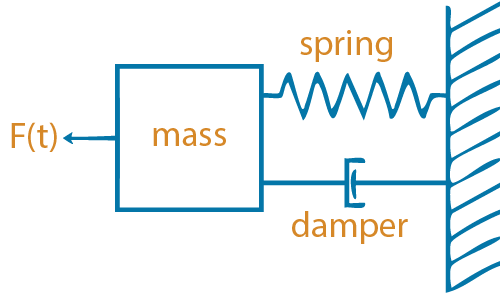

The motion of a damped harmonic oscillator is described by:

$m\ddot{x} + c\dot{x} + kx = F_0 \cos(\omega t)$.

where:

- $x$ = displacement as a function of time

- $m$ = mass

- $c$ = damping coefficient

- $k$ = spring constant

- $F_0$ = amplitude of driving force

- $\omega$ = driving angular frequency

### **Steady-State Solution**

The displacement in steady state is:


$$x(t) = A \cos(\omega t - \phi)$$


with a phase shift


$$\phi = \arctan\left(\frac{2\zeta \omega \omega_0}{\omega_0^2-\omega^2}\right)$$


and an amplitude:


$$A = \frac{F_0/m}{\sqrt{(\omega_0^2 - \omega^2)^2 + (2\zeta\omega\omega_0)^2}}$$


where:

- $\omega_0 = \sqrt{\frac{k}{m}}$   is the natural frequency,

- $\zeta = \frac{c}{2\sqrt{mk}}$ is the damping ratio.

### Homogeneous Solution

The homogeneous solution in the underdamped case is 


$$x_h(t) = e^{-\zeta \omega_0 t}\left(x(0)\cos(\omega_dt) + \frac{\dot{x}(0)+\zeta\omega_0x(0)}{\omega_d}\sin(\omega_d t)\right)$$
 

where 

- $x(0)$ is the initial position,

- $\dot{x}(0)$ is the initial velocity,

- $\omega_d = \omega_0\sqrt{1-\zeta^2}$ is the damped natural frequency.

### Complete Solution

The full solution is 

$x(t) = e^{-\zeta \omega_0 t}\left(x(0)\cos(\omega_dt) + \frac{\dot{x}(0)+\zeta\omega_0x(0)}{\omega_d}\sin(\omega_d t)\right) + \frac{F_0/m}{\sqrt{(\omega_0^2 - \omega^2)^2 + (2\zeta\omega\omega_0)^2}}\cos\left(\omega t- \arctan\left(\frac{2\zeta \omega \omega_0}{\omega_0^2-\omega^2}\right)\right)$.

 **Exercise 5.**

Prove that the complete solution presented above can be computed using the method of undetermined coefficients with a guess of $x_p = A\cos(\omega t - \phi)$.

**Solution:**

Work out your solution on paper or use this space to type up a solution.

### Pendulum Simulation with Resonance

Resonance in a **forced harmonic oscillator with damping** occurs when the driving frequency of an external periodic force is close to the system’s natural frequency, but damping modifies the behavior significantly compared to an ideal undamped system. 

 **Exercise 6.** In an idealized system with $c=0$, what is the particular solution when $\omega = \omega_0 = \sqrt{\frac{k}{m}}$? You can use the values `omega, m, k, t,` and `F_0`.

**Solution:**

syms F_0 m k t omega 
xp =  F_0*cos(omega*t);   
CheckExercise6(xp)

  **Try**. Explore how different parameters affect pendulum motion:

c = 1;
omega0 = 0.5;
F_0 = 0.5;
omega = 0.1;
theta0 = 1;
thetaPrime0 = -4;
PlotPendulum(c, omega0, F_0, omega, theta0, thetaPrime0,0);

## Application: Chemical Bonds

Chemical bonds between atoms behave like springs connecting masses. The amount of vibration is a measure of the energy (temperature!) of the molecule. When additional energy is applied—typically via electromagnetic radiation such as infrared (IR) light—these bonds can change the frequency of oscillation. This oscillation is known as **molecular vibration**, and it occurs in discrete energy levels governed by quantum mechanics. One simple approach is to model the stretching of a diatomic molecular bond as a harmonic oscillator subject to external perturbations. This starts with Hooke's Law: $\mu\ddot{x} = -kx$ where $k$ is the bond's force constant, $\mu = \frac{m_1m_2}{m_1+m_2}$ is the reduced mass of the two atoms. and $x$ is the displacement from equilibrium. Consider a diatomic molecule where the bond length oscillates about its equilibrium position:


$$x'' + \omega^2 x = F(t)$$


where $\omega^2 = \frac{k}{\mu}$ and $F(t)$ is an external forcing function. When a molecule is exposed to an external electromagnetic field (e.g., IR light), the field can **excite vibrational modes** if its frequency matches the energy gap between vibrational states. This is called resonant absorption.

### Example: Periodic External Force

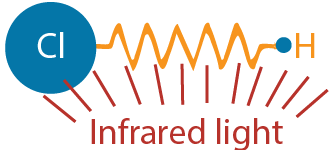

Consider a molecule of hydrogen chloride, HCl.  The mass of a hydrogen atom is approximately $1.67\times 10^{-27}~\text{kg}$ and the mass of a chlorine atom is approximately $5.90\times 10^{-26}~\text{kg}$. We can model this diatomic molecule as a harmonic oscillator with a reduced mass of $\mu = 1.62\times 10^{-27}~\text{kg}$. The resting bond length, $r_0$, is measured at approximately $1.275~\AA$. Its vibrational zero-point energy is $1443.0 \text{ cm}^{-1}$ and the fundamental frequency is $\tilde{\nu} = 2886 \text{ cm}^{-1}$. [1,2] 

Converting the wavenumber to an angular frequency, we have:


$$\omega_0 = 2\pi c \tilde{\nu} ~ \text{rad}/\text{s}$$


with $\tilde{\nu} = 2886 \text{ cm}^{-1}$ and $c = 3.00\times 10^{10} ~ \text{cm}/\text{s}$ as the speed of light. Plugging in the values, this gives us 

$\matrix{\omega_0 &=& 2\pi\times 2886 \times 3.00\times 10^{10} ~\text{rad}/\text{s} \cr &\approx& 5.42\times 10^{14} ~\text{rad}/\text{s}}$.

 **Exercise 7.** Solve for $k$ in this model. Keep an appropriate number of significant digits.

kHCl =  0 ;  
CheckExercise7(kHCl)

### Chemical Bond Visualization

  **Try.** Explore how different external frequencies affect bond oscillations of our modeled hydrogen chloride. Recall that infrared light spans a range from around $14,000~\text{cm}^{-1}$ to $10~\text{cm}^{-1}$, with mid-infrared in approximately the $4,000-400~\text{cm}^{-1}$range.

bond_omega = 2886;
external_freq =  2880;  
external_amp = 0.1;
PlotChemicalBond(bond_omega, external_freq, external_amp,0,12e-12);

## Further Exploration

There is additional exploration of the transient and steady-state solutions to a damped harmonic oscillator in the [Harmonic Oscillator Explorer](https://www.mathworks.com/matlabcentral/fileexchange/123715-harmonic-oscillator-explorer) by Duncan Carlsmith.

You can learn how to calculate symbolic solutions to ODEs in [CheckYourWork](matlab:open('.\CheckYourWork.mlx')). 

## References

[1] [https://cccbdb.nist.gov/exp2x.asp?casno=7647010&charge=0](https://cccbdb.nist.gov/exp2x.asp?casno=7647010&charge=0) 

[2] [https://en.wikipedia.org/wiki/Hydrogen_chloride](https://en.wikipedia.org/wiki/Hydrogen_chloride) 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternatively, select **Output inline** using the icon   at the top right of the Live Editor pane.

function PlotPendulum(gamma, omega0, F0, omega, theta0, thetaPrime0,tOffset)
    tVals = linspace(0, 20, 1000)+tOffset;
    
    syms theta(t)
    % Define the differential equation
    eqn = diff(theta, t, 2) + gamma*diff(theta, t) + omega0^2*theta == F0*cos(omega*t);
    eqnH = diff(theta, t, 2) + gamma*diff(theta, t) + omega0^2*theta == 0;
    Dtheta = diff(theta,t);

    % Solve the differential equation
    theta_sol = dsolve(eqn,[theta(0)==theta0 Dtheta(0)==thetaPrime0]);
    theta_homog_sol = dsolve(eqnH,[theta(0)==theta0 Dtheta(0)==thetaPrime0]);
    
    % Convert the solution to a function for plotting
    theta_func = matlabFunction(theta_sol);
    if theta_homog_sol == 0
        theta_transient = zeros(size(tVals));
    else
        theta_homog_func = matlabFunction(theta_homog_sol);
        theta_transient = theta_homog_func(tVals);
    end
    
    theta_total = theta_func(tVals);

    theta_steadystate = theta_total - theta_transient;

    figure;
    tiledlayout(2,1);
    
    nexttile;
    plot(tVals, theta_transient, 'r--', 'LineWidth', 1.5);
    hold on;
    plot(tVals, theta_steadystate, 'b-', 'LineWidth', 1.5);
    plot(tVals, theta_total, 'k-', 'LineWidth', 2);
    xlabel('Time');
    ylabel('Angular Displacement θ');
    legend('Transient (θ_h)', 'Steady State (θ_p)', 'Total Solution', 'Location', 'best');
    title('Pendulum Motion Components');
    grid on;
    
    nexttile;
    plot(tVals, F0*cos(omega*tVals), 'g-', 'LineWidth', 1.5);
    hold on;
    plot(tVals, theta_total, 'k-', 'LineWidth', 2);
    xlabel('Time');
    ylabel('Amplitude');
    legend('Driving Force', 'Response', 'Location', 'best');
    title('Driving Force vs Response');
    grid on;
    
    fprintf('Parameters: γ=%.2f, ω₀=%.2f, F₀=%.2f, ω=%.2f\n', gamma, omega0, F0, omega);
    displayFormula("theta_homog_sol")
    if abs(omega - omega0) < 0.1
        fprintf('⚠ Near resonance condition!\n');
    end
end

function PlotChemicalBond(wv0, wavenum, F0,tStart,tEnd)
    tVals = linspace(tStart, tEnd, 1000);
    omega0 = 2*pi*3e10*wv0;
    omega = 2*pi*3e10*wavenum;

    % Particular solution
    if abs(1-wv0/wavenum) > 1e-6
        % Non-resonant case
        A = F0/(omega0^2 - omega^2);
        x_h = -A*cos(omega0*tVals);
        x_p = A*cos(omega*tVals);
    else
        % Near resonance - use modified form
        A = F0/(2*omega0);
        x_p = A*tVals.*sin(omega0*tVals);
        x_h = -A*sin(omega0*tVals);
    end

    % Total solution
    x_total = x_h + x_p;

    figure
    tiledlayout(2,1);
    
    nexttile
    plot(tVals, x_total, 'b-', 'LineWidth', 1.5);  
    xlabel('Time (s)');
    ylabel('Bond Displacement (m)');
    % legend('Total Motion', 'Location', 'best');
    title('Chemical Bond Oscillation');
    grid on;
    
    nexttile
    waveVals = 1000:2:4000; % wavenumber
    ampVals = abs(F0/(4*pi^2*9e20)./(2886^2-waveVals.^2));
    ampVals(waveVals==2886) = F0/(4*pi*3e10*2886);
    semilogy(waveVals,ampVals,LineWidth=2)
    title("Frequency response of HCl model")
    xlabel("Wavenumber of IR light")
    ylabel("Amplitude of HCl Oscillation")

    fprintf('Bond wavenumber: %.0f, External wavenumber: %.0f, Response Amplitude: %.4e\n', ...
        omega0/(2*pi*3e10), omega/(2*pi*3e10), A);
end

function [diffeq,RHS] = GenerateProblem(type,overlap)
arguments
    type (1,1) string {mustBeMember(type,["poly","exp","sincos","any"])}
    overlap (1,1) logical = false
end

if type == "any"
    opts = ["poly" "exp" "sincos" "polyexp" "expsincos" "polysincos" "all"];
    idx = randi(7);
    choice = opts(idx);
    overlap = randi(3)-1;
else
    choice = type;
    overlap = double(overlap);
end

if contains(choice,"sincos") || choice == "all"
    if overlap
        overlap = 1;
    else
        overlap = 0;
    end
end

% Generate many random constants
constants = randi([-5, 5],[7,1]);
if constants(1) == 0
    constants(1) = 1;
end


syms x y(x)
deg = randi(4,1);
n = 0;      % The maximum degree of a polynomial
alpha = 0;  % The argument for sincos
beta = 0;   % The argument for exp

switch choice
    case "poly"
        g = x.^(deg:-1:0)*constants(1:deg+1);
        n = deg;
    case "exp"
        if constants(2) ~= 0
            beta = constants(2);
        else
            beta = -1;
        end
        g = constants(1) * exp(beta * x);
    case "sincos"
        if constants(2) ~= 0
            alpha = constants(2);
        else
            alpha = 1;
        end
        if logical(randi(2)-1)
            g = constants(1)*sin(alpha*x);
        else
            g = constants(1)*cos(alpha*x);
        end
    case "polyexp"
        beta = constants(deg+2);
        g = x.^(deg:-1:0)*constants(1:deg+1)*exp(beta*x);
    case "expsincos"
        alpha = constants(2);
        beta = constants(3);
        if logical(randi(2)-1)
            g = constants(1)*sin(alpha*x)*exp(beta*x);
        else
            g = constants(1)*cos(alpha*x)*exp(beta*x);
        end
    case "polysincos"
        alpha = constants(deg+2);
        n = deg;
        if logical(randi(2)-1)
            g = x.^(deg:-1:0)*constants(1:deg+1)*sin(alpha*x);
        else
            g = x.^(deg:-1:0)*constants(1:deg+1)*cos(alpha*x);
        end
    case "all"
        opt = randi(3);
        alpha = constants(deg+2);
        beta = constants(end);
        if opt == 1
            g = x.^(deg:-1:0)*constants(1:deg+1)*sin(alpha*x)*exp(beta*x);
        elseif opt == 2
            g = x.^(deg:-1:0)*constants(1:deg+1)*cos(alpha*x)*exp(beta*x);
        else
            deg2 = randi(4);
            g = (x^deg*constants(1)*sin(alpha*x)+x^deg2*constants(2)*cos(alpha*x))*exp(beta*x);
            n = max(deg,deg2);
        end
        
end

RHS.power = n;
RHS.beta = beta;
RHS.alpha = alpha;
RHS.type = choice;
RHS.overlap = overlap;

homogType = ChooseHomogType(RHS);
[diffeq,RHS] = GenerateHomogProblem(homogType,RHS);

diffeq.full = diffeq.LHS == g;
displayFormula(['"Solve "'; "diffeq.full"])
end

function homogType = ChooseHomogType(RHS)
    if RHS.overlap == 0
        homogType = "any";
    else
        if RHS.alpha
            homogType = "complex";
        elseif RHS.beta
            homogType = "real";
        else
            homogType = "repeated";
        end
    end
end

function [diffeq,RHS] = GenerateHomogProblem(type,RHS)
arguments
    type (1,1) string {mustBeMember(type,["real","repeated","complex","any"])}
    RHS
end

if type == "any"
    opts = ["real" "repeated" "complex"];
    idx = randi(3);
    choice = opts(idx);
else
    choice = type;
end

[LH,a,v] = CreatePolynomial();

switch choice
    case "real"
        while v(1) == v(2)
            [LH,~,v] = CreatePolynomial();
        end
    case "repeated"
        LH = a*poly([v(1) v(1)]);
    case "complex"
        Delta1 = v(1)^2 - 4*a*v(2);
        Delta2 = v(1)^2 + 4*a*v(2);
        while Delta1 >= 0 && Delta2 >= 0
            [~,a,v] = CreatePolynomial();
            Delta1 = v(1)^2 - 4*a*v(2);
            Delta2 = v(1)^2 + 4*a*v(2);
        end
        if Delta1 < 0
            LH = [a v];
        else
            LH = [-a v];
        end
end
if RHS.overlap
    if choice == "complex"
        LH = a*poly([RHS.alpha+RHS.beta*1i RHS.alpha-RHS.beta*1i]);
    else
        if RHS.overlap == 1 && choice == "real"
            if v(2) ~= RHS.beta
                LH = a*poly([RHS.beta v(2)]);
            else
                LH = a*poly([RHS.beta v(1)]);
            end
        else
            LH = a*poly([RHS.beta RHS.beta]);
        end
    end
end

syms x y(x)
roots = solve(LH*[x^2;x;1]);

if ~RHS.overlap
    if RHS.type == "complex" && ~isreal(roots(1))
        if RHS.alpha == real(roots(1)) && RHS.beta == abs(imag(roots(1)))
            LH = a*poly([RHS.alpha-1+RHS.beta*1i RHS.alpha-1-RHS.beta*1i]);
            roots = [RHS.alpha-1+RHS.beta*1i RHS.alpha-1-RHS.beta*1i];
        end
    elseif RHS.type ~= "complex" && any(roots == 0)
        coeffs = randi(10,[1 2]);
        LH = a*poly([coeffs(1) -coeffs(2)]);
        roots = [coeffs(1) -coeffs(2)];
    end
end

diffeq.LHS = LH(1)*diff(y,x,2)+LH(2)*diff(y,x)+LH(3)*y;
diffeq.homog = diffeq.LHS == 0;
RHS.homogtype = choice;
RHS.roots = roots;
RHS.LHS = LH;

end

function [LH,a,v] = CreatePolynomial()
v = randi(11,[1 2])-6;
a = (randi(2,1)-1)*(randi(11,1)-6);
if a == 0
    a = 1;
end
LH = a*poly(v);
end


function CheckGuess(MyGuess,RHS,DefaultAns)
arguments
    MyGuess 
    RHS 
    DefaultAns
end
if MyGuess == DefaultAns
    disp("This is the default. Please enter a solution and resubmit.")
    return
end
syms x A B C D E F G H I J
coeffs = [A B C D E F G H I J];

OverlapDegree = RHS.overlap;

MyGuess = simplify(MyGuess);

polyFun = [coeffs(1:RHS.power+1)*x.^((RHS.power:-1:0)') coeffs(RHS.power+2:2*RHS.power+2)*x.^((RHS.power:-1:0)')];
expFun = exp(RHS.beta*x);
alpha = abs(RHS.alpha);
sincosFun = [cos(alpha*x); sin(alpha*x)];

ySoln1 = polyFun*sincosFun*expFun*x^OverlapDegree;
ySoln2 = polyFun*flipud(sincosFun)*expFun*x^OverlapDegree;

if isAlways((ySoln1 == MyGuess)||(ySoln2 == MyGuess))
    disp("Correct!")
    syms y_p
    displayFormula(['"The guess is "' "y_p = MyGuess"])
elseif alpha ~= RHS.alpha
    sincosFunSigned = [cos(alpha*x); -sin(alpha*x)];
    ySoln1Signed = polyFun*sincosFunSigned*expFun*x^OverlapDegree;
    ySoln2 = polyFun*flipud(sincosFunSigned)*expFun*x^OverlapDegree;
    if isAlways((ySoln1Signed == MyGuess)||(ySoln2 == MyGuess))
        disp("Technically correct!")
        syms y_p
        displayFormula(['"Conventionally, this guess is written with positive coefficients as "' "y_p = ySoln1"])
    else
        displayFormula(['"Does your guess include both "' "sin(alpha*x)" '" and "' "cos(alpha*x)" '"?"'])
    end
else
    if RHS.type == "poly"
    try
    if polynomialDegree(MyGuess) ~= polynomialDegree(ySoln1)
        disp("This is not the right degree. Notice that g(x) was of degree " + RHS.power + ".")
    else
        disp("Please check your coefficients. Did you use A, B, C, etc? Did you include all terms?")
        disp("Did you write your guess with addition only? All signs can be absorbed into the coefficients.")
    end
    catch ME
        disp("This should only be a polynomial.")
    end
    end
    if contains(RHS.type,"exp")
        displayFormula(['"Does your guess include "' "exp(RHS.beta*x)"  '"?"'])
        displayFormula(['"Is "' "exp(RHS.beta*x)" '" a homogeneous solution?"'])
    end
    if contains(RHS.type,"sincos")
        displayFormula(['"Does your guess include both "' "sin(alpha*x)" '" and "' "cos(alpha*x)" '"?"'])
    end
    if RHS.type == "all" 
        displayFormula(['"Does your guess include both "' "polyFun(1)" '" and "' "polyFun(2)" '"?"'])
        displayFormula(['"Is "' "exp(RHS.beta*x)*cos(RHS.alpha*x)" '" a homogeneous solution?"'])
    end
    if OverlapDegree ~= 0 && subs(MyGuess,x,0) ~= 0
        disp("Did you check the homogeneous solutions?")
    end
    if RHS.power > 0
        disp("Do you use coefficients A, B, C, ... in alphabetical order?")
    end
end
end


function out = CheckParticularSolution(yP,diffeq,DefaultAnswer)
out = false;
if yP == DefaultAnswer
    disp("This is the default. Please enter a solution and resubmit.")
    return
end
yh = dsolve(diffeq.homog);
ytot = dsolve(diffeq.full);
ySoln = ytot-yh;
if isAlways(yP==ySoln,"Unknown","false")
    disp("Correct!")
    displayFormula("y_p == yP")
    out = true;
elseif isAlways(yP==ytot,"Unknown","false")
    displayFormula('"That isn''t the particular solution from the method of undetermined coefficients!"')
    displayFormula('"It looks like you included the general homogeneous terms, too."')
    displayFormula(['"What does this look like if you solve for the minimal "' "y_p" '" with "' "y_h==0" '"?"'])
else
    disp("Please try again.")
end
end

function out = CheckHomogSolution(yH,diffeq,DefaultAns)
out = false;
if yH == DefaultAns
    disp("This is the default. Please enter a solution and resubmit.")
    return
end
syms x C1 C2 C3 C4 y(x) coeff1 coeff2
assume(x,"real")
assume(C1,"real")
assume(C2,"real")
GenSol = subs(yH,[C1 C2],[coeff1 coeff2]);
GenSol1a = subs(GenSol,[coeff1 coeff2],[C1 C2]);
GenSol2a = subs(GenSol,[coeff1 coeff2],[C2 C1]);
GenSol1b = subs(GenSol,[coeff1 coeff2],[C1 -C2]);
GenSol2b = subs(GenSol,[coeff1 coeff2],[C2 -C1]);
GenSolAns = dsolve(diffeq.homog);
GenSolAns = subs(GenSolAns,[C3 C4],[C1 C2]);
ytot = dsolve(diffeq.full);
if isAlways(GenSol1a==GenSolAns,"Unknown","false") || isAlways(GenSol2a==GenSolAns,"Unknown","false") ...
        || isAlways(GenSol1b==GenSolAns,"Unknown","false") || isAlways(GenSol2b==GenSolAns,"Unknown","false") ...
        || isAlways(-GenSol1a==GenSolAns,"Unknown","false") || isAlways(-GenSol2a==GenSolAns,"Unknown","false") ...
        || isAlways(-GenSol1b==GenSolAns,"Unknown","false") || isAlways(-GenSol2b==GenSolAns,"Unknown","false")
    disp("Correct! The solution is: ")
    displayFormula("y(x) == GenSol1a")
    out = true;
elseif isAlways(GenSol1a == C1*x + C2*exp(4*x),"Unknown","false")
    disp("This is the default solution.")
elseif imag(yH) ~= 0
    displayFormula(['"You wrote "' "y(x) == GenSol1a" '" but your answer should not involve complex values."'])
    displayFormula('"Please express your solution with only real values. Use sines and cosines if necessary."')
    disp('Review Characteristic Equations')
elseif isAlways(yP==ytot,"Unknown","false")
    displayFormula('"That isn''t the homogeneous solution from the method of undetermined coefficients!"')
    displayFormula('"It looks like you included the particular solution terms, too."')
    displayFormula(['"Remember that the homogeneous solution solves "' "diffeq.homog"])
else
    displayFormula('"Incorrect. Please try again."')
    displayFormula(['"Remember that the homogeneous solution solves "' "diffeq.homog"])
end
assume(x,"clear")
assume(C1,"clear")
assume(C2,"clear")
end

function CheckExercise6(xp)
syms F_0 omega t m k x_p(t)
if isAlways(xp==F_0*cos(omega*t),"Unknown","false")
    disp("This is the default value. The solution is not just the forcing function.")
elseif isAlways(xp == F_0/(2*sqrt(m*k))*t*sin(omega*t),"Unknown","false")
    disp("Correct!")
    displayFormula(['"The steady-state solution is "' "x_p(t) == xp" '"."'])
elseif subs(xp,t,0) ~= 0
    disp("Incorrect. Remember that your particular solution must be linearly independent of the homogeneous solution.")
elseif isAlways(xp == F_0/(2*sqrt(m*k))*sin(omega*t),"Unknown","false")
    disp("Incorrect. Did you forget a factor of t?")
else
    disp("Incorrect. Remember to use the value omega and NOT omega_0. You can also use m, k, t, and F_0.")
end
end

function CheckExercise7(kAns)
kHCl = round(1.62e-27 * (5.42e14)^2,0); % Calculate k for HCl
if kAns == kHCl
    disp("Correct!")
    displayFormula(['"The computed value for the spring coefficient for HCl is approximately "'  "kHCl" '" N/m."'])
elseif kAns == 0
    disp("This is the default. The spring constant is not 0.")
elseif abs(kAns-kHCl)<1
    disp("Close enough, though you kept more precision than is appropriate given the values provided.")
    displayFormula(['"The computed value for the spring coefficient for HCl is approximately "'  "kHCl" '" N/m."'])
elseif abs(kAns-480)<1e-1
    disp("This is a common number given online, but doesn't match the values given in this problem.")
    disp("Please try again.")
else
    disp("Incorrect.")
    syms omega_0
    displayFormula(['"Remember that "' "omega_0 = sqrt(k/mu)"])
end
end